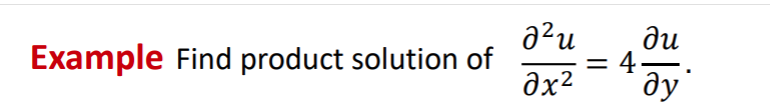

clear;
clf;
clc
syms x y u(x,y) 

**PDE**

Eq = diff(u,x,2) == 4*diff(u,y)

$$Eq(x, y) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,y\right)=4\,\frac{\partial }{\partial y}u\left(x,y\right)$$

syms X(x) Y(y)
Sepvar = subs(Eq,u(x,y),X(x)*Y(y))

$$Sepvar(x, y) = Y\left(y\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=4\,X\left(x\right)\,\frac{\partial }{\partial y}Y\left(y\right)$$

**Separate Variable ot the equation**

Sepvar = Sepvar/(4*X(x)*Y(y))

$$Sepvar(x, y) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{4\,X\left(x\right)}=\frac{\frac{\partial }{\partial y}Y\left(y\right)}{Y\left(y\right)}$$

**Separate ODEs introduce constant(Lambda)^2**

var = children(Sepvar)

var = 1×2 cell array
    {[diff(X(x), x, x)/(4*X(x))]}    {[diff(Y(y), y)/Y(y)]}


syms lambda
assume(lambda,"positive")
eqX = var(1) == lambda

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{4\,X\left(x\right)}=\lambda$$

eqY = var(2) == lambda

$$eqY = \frac{\frac{\partial }{\partial y}Y\left(y\right)}{Y\left(y\right)}=\lambda$$

Y(y,lambda) = dsolve(eqY)

$$Y(y, lambda) = C_{1}\,{\mathrm{e}}^{\lambda \,y}$$

X(x,lambda) = dsolve(eqX)

$$X(x, lambda) = C_{1}\,{\mathrm{e}}^{-2\,\sqrt{\lambda }\,x}+C_{2}\,{\mathrm{e}}^{2\,\sqrt{\lambda }\,x}$$

**Lambda = 0**

X(x) = dsolve(subs(eqX,lambda,0))

$$X(x) = C_{2}+C_{1}\,x$$

Y(y) = dsolve(subs(eqY,lambda,0))

$$Y(y) = C_{1}$$

U_0(x,y) = X(x)*Y(y)

$$U\_0(x, y) = C_{1}\,\left(C_{2}+C_{1}\,x\right)$$

eq1 = (subs(X,x,0)) == 0

$$eq1(x) = C_{2}=0$$

syms C2 L
eq2 = (subs(X,[x,C2],[L,0])) == 0

$$eq2(x) = C_{1}\,L=0$$

**Lambda = -alpha^2**

syms alpha C1 C2
X(x) = dsolve(subs(eqX,lambda,-alpha^2))

$$X(x) = C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x\,\mathrm{i}}$$

cond1 = subs(X,x,0) == 0

$$cond1(x) = C_{1}+C_{2}=0$$

cond2 = subs(X,x,L) == 0

$$cond2(x) = C_{1}\,{\mathrm{e}}^{-2\,L\,\alpha \,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{2\,L\,\alpha \,\mathrm{i}}=0$$

[C1,C2] = solve([cond1,cond2],[C1,C2])

$$C1 = 0$$

$$C2 = 0$$

Y(y) = dsolve(subs(eqY,lambda,-alpha^2))

$$Y(y) = C_{1}\,{\mathrm{e}}^{-\alpha^{2}\,y}$$

U(x,y) = X(x)*Y(y)

$$U(x, y) = C_{1}\,{\mathrm{e}}^{-\alpha^{2}\,y}\,\left(C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x\,\mathrm{i}}\right)$$

eq1 = (subs(X,x,0)) == 0

$$eq1(x) = C_{1}+C_{2}=0$$

syms C1 C2 L
eq2 = collect(subs(X,[x,C2],[L,C1]),C1) == 0

$$eq2(x) = \left({\mathrm{e}}^{-2\,L\,\alpha \,\mathrm{i}}+{\mathrm{e}}^{2\,L\,\alpha \,\mathrm{i}}\right)\,C_{1}=0$$

**Lambda = alpha^2**

syms alpha
X(x) = dsolve(subs(eqX,lambda,alpha^2))

$$X(x) = C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x}$$

Y(y) = dsolve(subs(eqY,lambda,alpha^2))

$$Y(y) = C_{1}\,{\mathrm{e}}^{\alpha^{2}\,y}$$

U(x,y) = X(x)*Y(y)

$$U(x, y) = C_{1}\,{\mathrm{e}}^{\alpha^{2}\,y}\,\left(C_{1}\,{\mathrm{e}}^{-2\,\alpha \,x}+C_{2}\,{\mathrm{e}}^{2\,\alpha \,x}\right)$$

eq1 = (subs(X,x,0)) == 0

$$eq1(x) = C_{1}+C_{2}=0$$

syms C1 C2 L
eq2 = collect(subs(X,[x,C2],[L,C1]),C1) == 0

$$eq2(x) = \left({\mathrm{e}}^{-2\,L\,\alpha }+{\mathrm{e}}^{2\,L\,\alpha }\right)\,C_{1}=0$$

exp(-2)+exp(2)

ans = 7.5244

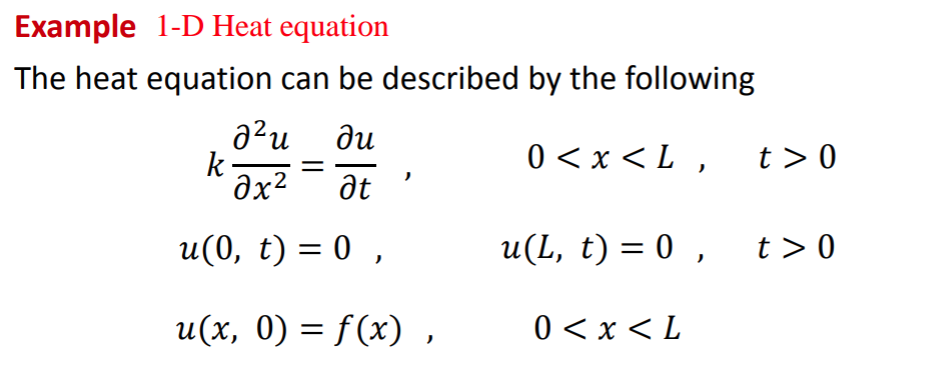

clear
clf
clc
syms x y u(x,t) L K
assume ([L  K],"positive")

**Heat equa**

HeatEq = diff(u,t) == K*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=K\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0;BCL = u(L,t) == 0;

syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)=K\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)$$

**Sepation Va**

BCx0 = subs(BC0,u(0,t),X(0)*T(t)/T(t))

$$BCx0 = X\left(0\right)=0$$

BCxL = subs(BCL,u(0,t),X(L)*T(t)/T(t))

$$BCxL = u\left(L,t\right)=0$$

Seperate variable of the equation 

SepVar = SepVar/(K*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{K\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

var = children (SepVar)

var = 1×2 cell array
    {[diff(T(t), t)/(K*T(t))]}    {[diff(X(x), x, x)/X(x)]}


syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{K\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

%solve ODEs
T(t,lambda) = dsolve(eqT) %1st order for T

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-K\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0); %2nd order for X using X(0) = 0

**Replace constant in X**


constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

**Add an arbittrary multiplier(replace k with n)**

sin = X(L,lambda);
[lambda,parameters,conditions] = solve(sin == 0,lambda,"ReturnConditions",true)

$$lambda = \frac{\pi \,k}{L}$$

$$parameters = k$$

$$conditions = k\in \mathbb{Z}\wedge C_{2}\neq 0\wedge 1\leq k$$

n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,n}{L}$$

**Back to solution structture**

**Raplace lamda = n*Pi/L and b_n = C2**

syms b_n ustuct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);

**Back to product solution**

ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin" "exp"])

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{K\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

From symbolic to function handle

SinXExpTfun = matlabFunction(ustruct)

SinXExpTfun = function_handle with value:
    @(x,t,n,K,L,b_n)b_n.*exp(-K.*1.0./L.^2.*n.^2.*t.*pi.^2).*sin((n.*x.*pi)./L)


syms x m n L e(n)
assume([m,n],["integer","positive"]); assume(L,"positive"); assumeAlso(not(L == pi));
lambda(n) = n*pi/L;
e(n) = sin(lambda(n)*x)

Error using indexing
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

Error in indexing (line 968)
            R_tilde = builtin('subsref',L_tilde,Idx);

Related documentation

check_orthogonality = int(e(n)*e(m),0,L)
syms x t n b(n) phi(x)
assume(n,"integer")
L = 4
phi(x) = piecewise(x<L/2,x,x>L/2,L/2);
fplot(phi), grid 0n
D = 0.1
N = 8

**Compute Fourier coefficients using phi(x) and L**

b(n) = simplify(2/L*int(phi(x)*sin(n*x*pi/L),0,L))
heatStruct = buildHeatStruct
heatstructEmb(x,t,n)= subs(heatStruct,sym(["b_n "L" "D"]),[b L D])

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

**HwR AOLURION**

Solutiion = symsum(heatstructEmb,n,1,inf)

**Buld the solution by summing up N terms of the series**

heatSolN= simplify(symsm(heatstruc))